Part 1-Read image

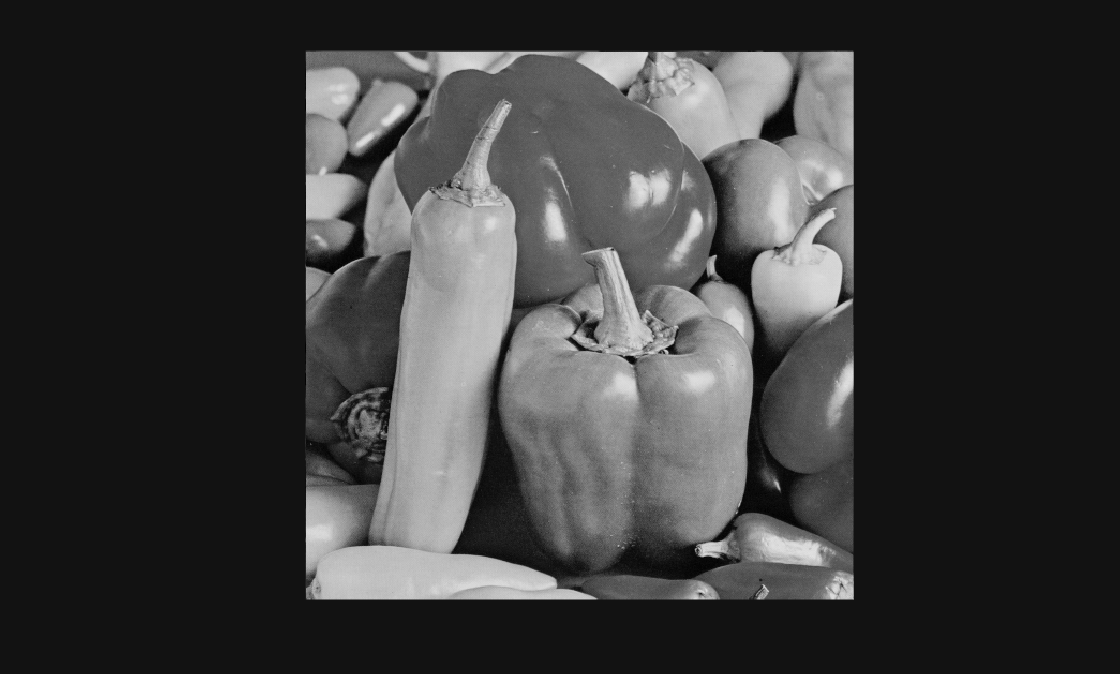

img = imread("pepper.bmp");
img_gray = im2gray(img);
img_double = im2double(img_gray);
imshow(img_double)

Part 2- motion blur

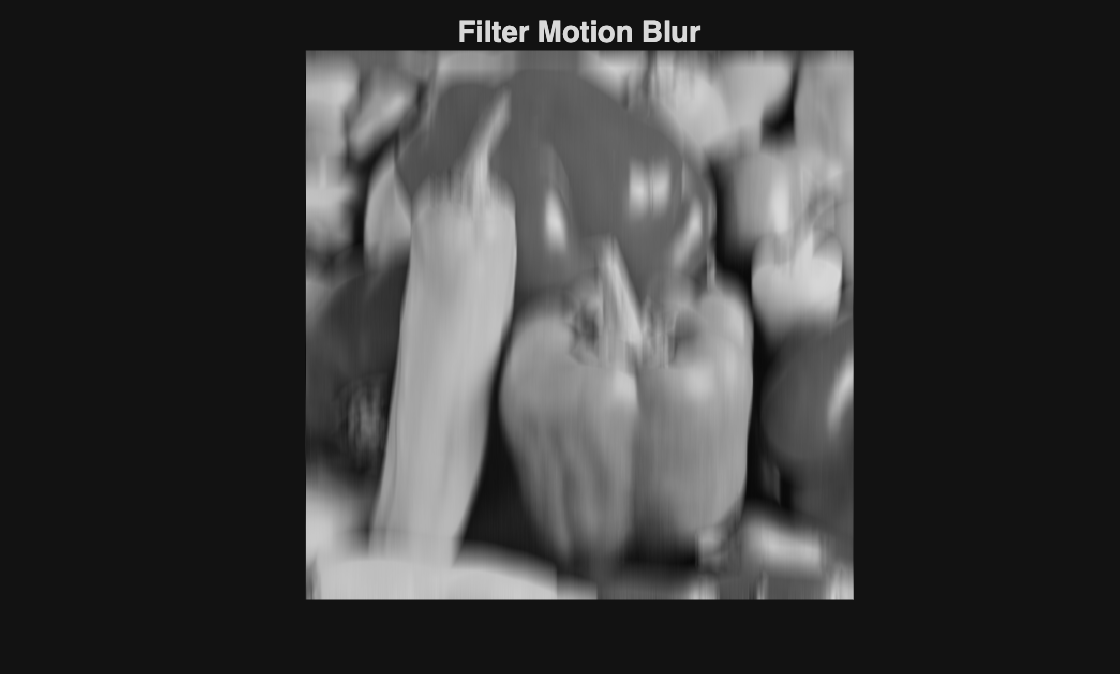

len = 30;
angle = 90;
filter_motion = fspecial("motion", len, angle);
img_motion = imfilter(img_double, filter_motion, "replicate");
imshow(img_motion)
title("Filter Motion Blur")

Part 3-Defocus

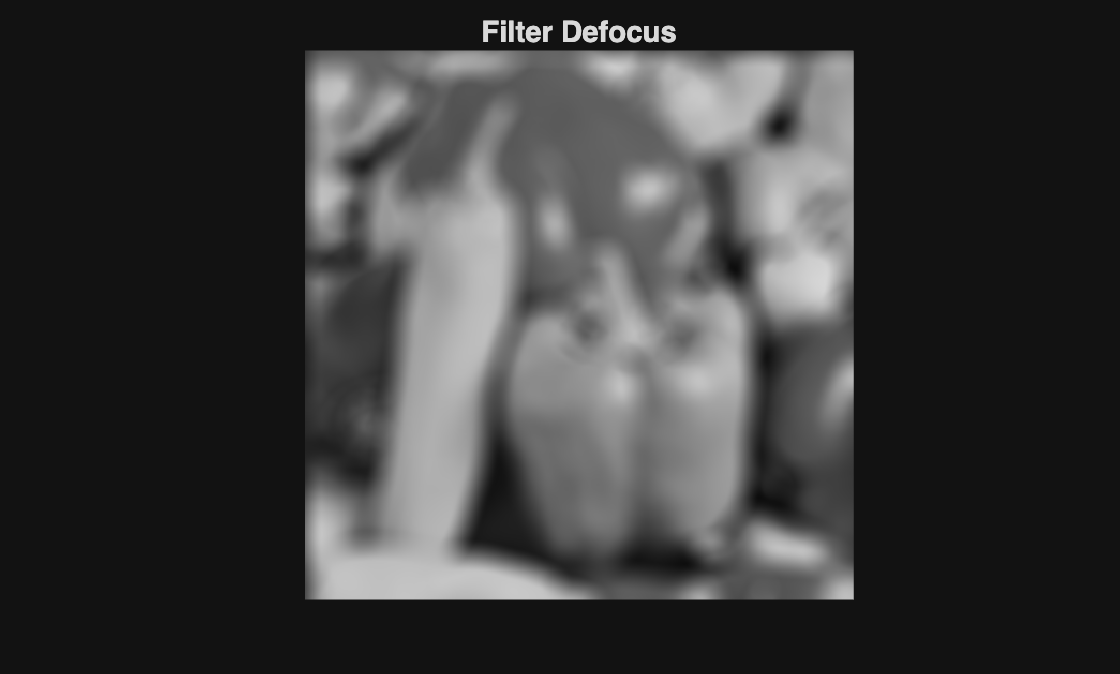

radius = 15;

filter_defocus = fspecial("disk", radius);
img_defocus = imfilter(img_double, filter_defocus, "replicate");
imshow(img_defocus)
title("Filter Defocus")

Part 4-Edge detection

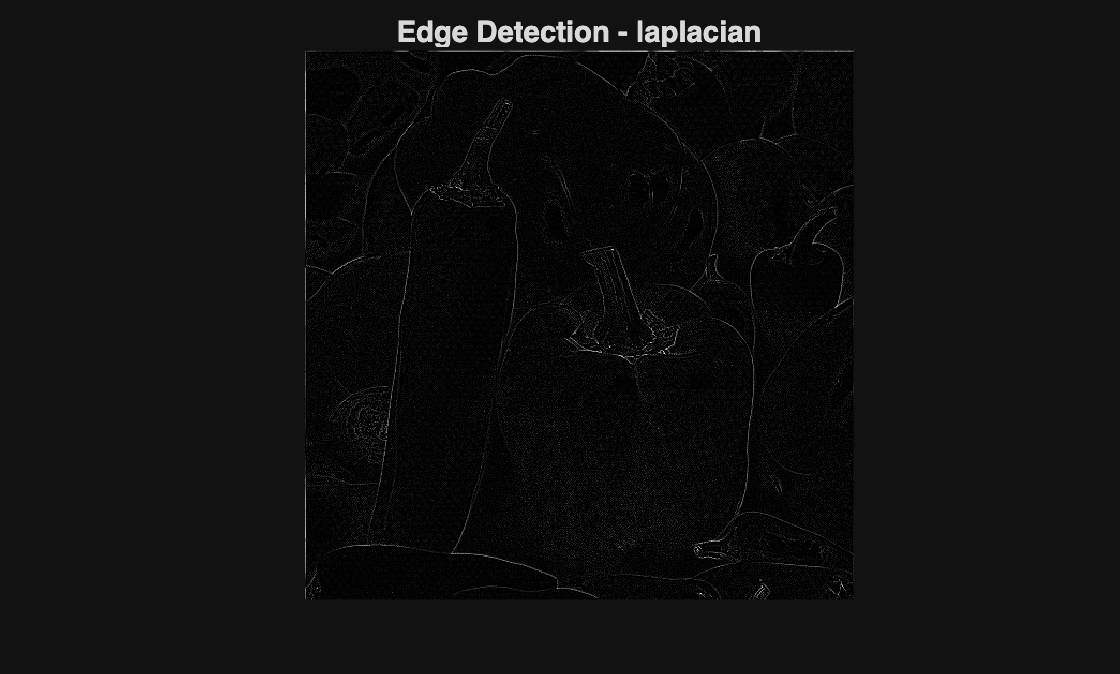

operator = "laplacian";

filter_edges = fspecial(operator);
img_edges = imfilter(img_double, filter_edges, "replicate");
imshow(img_edges)
title("Edge Detection - " + operator)